# Matlab Project: Confronto metodi di risoluzione sistemi lineari

Intendo determinare quale dei metodi di risoluzione di sistemi lineari sia il più efficiente, dal punto di vista della velocità di risoluzione e della stabilità, ed in quali circonstanze sia preferibile un metodo piuttosto che un altro. 

Prenderò in considerazione: risol. da fatt_LU, con pivoting parz. e totale; risol. da fatt_QR (con matrici di Householder); metodo di Jacobi; metodo di Richardson; e metodo del gradiente.

clear variables
close all

test = input('Quale test vuoi eseguire? \n');
Tol = 2.2e-16;                           % tolleranza per il test di arresto sui residui e per i valori nulli
c = 21;                                % numero di matrici su cui faccio i test
N = linspace(10,510,c);                % dimensioni delle matrici per i test
matr_b = cell(c,2);                    % salvo qui le matrici e i vettori b, (Ax = b), dei test

## Test 1: considero solo matrici SPD a dominanza diagonale, non mal condizionate (cond(A)≃ 1)

if test == 1
    for i = 1:c
        n = N(i);
        A = rand(n);
        A = A'*A;                      % creo A casuale in modo che sia simmetrica
        delta = norm(A);
        for j = 1:n
            somma = sum(abs(A(j,[1:j-1,j+1:n])));  
            A(j,j) = somma + delta;    % modifico la diagonale in modo che A sia a dominanza diag e SPD  
        end
        matr_b{i,1} = A; 
        matr_b{i,2} = rand(n,1);
    end
end

## Test 2: considero delle matrici randomiche

Scelgo matrici randomiche, garantendo sempre che non siano singolari. Siccome non sono SPD, o a dominanza diagonale, i metodi iterativi non convergono praticamente mai su queste matrici, quindi li escludo dai test.

if test == 2
    for i = 1:c
        n = N(i);
        A = rand(n);                   % creo A casuale
        while rcond(A) < 1e-16         % se è singolare la cambio
            A = rand(n);
        end
        matr_b{i,1} = A;               
        matr_b{i,2} = rand(n,1);
    end
end

## Test 3: considero delle matrici mal condizionate

In particolare scelgo la matrice di Poisson e b lo scelgo considerando il problema del filo elastico con -u''(x) = x, su [0,1], discretizzato in n+2 punti, la matrice è n*n.

if test == 3
    for i = 1:c
        n = N(i);
        h = 1/(n+1);
        e = ones(n,1);
        A = spdiags([-e 2*e -e], -1:1, n, n)/h^2; % creo A di Poisson, n+1 è il numero di intervalli
        x = (1:n)' * h;                           % creo il vettore x, con solo i punti interni, corrispondente al problema
        matr_b{i,1} = A;
        matr_b{i,2} = x;                          % applico -u''(x) = x
    end
end  
clear n_root A b n x e somma delta j

## Misuro il tempo di esecuzione e l'errore relativo

LU_tm = zeros(c,2);
LU_piv_tm = zeros(c,2);
QR_tm = zeros(c,2);
Jacobi_tm = zeros(c,2);
Richardson_tm = zeros(c,2);
Gradiente_tm = zeros(c,2);
ground_truth = cell(c,1);

for i = 1:c

    if test ~= 3                                    % nei casi in cui la matrice ha cond non troppo alto
        ground_truth{i} = matr_b{i,1}\matr_b{i,2};  % prendo come valore di 'verità' il risolutore di Matlab

    else                                            % se testo sulle matrici di Poisson so già la soluzione
        xi =  matr_b{i,2};                          % uso f(x) = x per ottenere la grigia xi, da −u′′(x)=x
        ux = (xi-xi.^3)./6;                         % dalla soluzione continua applicata sulla griglia 
        ground_truth{i} = ux;
    end
end


for i = 1:c

    % Estraggo le informazioni sulla matrice A,b e il risultato aspettato x
    A = matr_b{i,1};
    b = matr_b{i,2};
    real_x = ground_truth{i};
    norm_x = norm(real_x);
    IT_Tol = Tol * norm(b);
    LU_Tol = Tol * norm(A,'inf');
    
    % Risoluzione da Fatt_LU con pivoting parziale
    tic;
    [L,U,P] = Fatt_LU(A, LU_Tol);               % costo O((n^3)/3)
    y = Triang_Inf(L, P*b);                     % costo O((n^2)/2)
    x = Triang_Sup(U,y);                        % costo O((n^2)/2)
    LU_tm(i,1) = toc;
    LU_tm(i,2) = norm(real_x - x)/norm_x;

    % Risoluzione da Fatt_LU con pivoting totale
    tic;
    [L,U,P] = Fatt_LU_piv(A, IT_Tol);            % costo aumentato di O(n^2), non significativo
    y = Triang_Inf(L, P*b);                      % costo O((n^2)/2)
    x = Triang_Sup(U,y);                         % costo O((n^2)/2)
    LU_piv_tm(i,1) = toc;
    LU_piv_tm(i,2) = norm(real_x - x)/norm_x;
    clear L U P;

    % Fatt_QR
    tic;
    [Q,R] = Fatt_QR(A);
    x = Triang_Sup(R, Q'*b);                     % costo O((n^2)/2)
    QR_tm(i,1) = toc;
    QR_tm(i,2) = norm(real_x - x)/norm_x;
    clear Q R

    % Jacobi
    if test ~= 2
        tic;
        x = Jacobi(A,b,IT_Tol);
        Jacobi_tm(i,1) = toc;
        Jacobi_tm(i,2) = norm(real_x - x)/norm_x;

        % Gradiente
        tic
        x = Gradiente(A, b, IT_Tol);
        Gradiente_tm(i,1) = toc;
        Gradiente_tm(i,2) = norm(real_x - x)/norm_x;
    
        % Richardson
        tic;
        x = Richardson(A,b,IT_Tol);              % velocità di convergenza (K2(A)-1)/K2(A)+1)
        Richardson_tm(i,1) = toc;
        Richardson_tm(i,2) = norm(real_x - x)/norm_x;
    end

end
clear x y real_x norm_x i A b LU_Tol

## Visualizzazione dei risultati con Plot in scala semilog

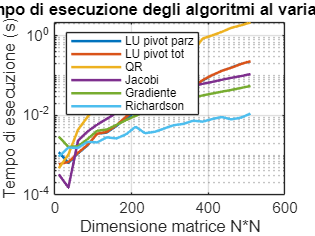

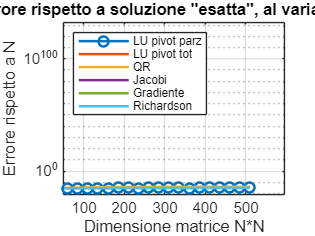

close all

% Visualizzo il tempo di esecuzione al variare di N
if test==1 || test==3
    figure;
    semilogy(N,LU_tm(:,1), ...
             N, LU_piv_tm(:,1), ...
             N, QR_tm(:,1), ...
             N, Jacobi_tm(:,1), ...
             N, Gradiente_tm(:,1), ...
             N, Richardson_tm(:,1), 'LineWidth',1.5);
    grid on;
    xlabel('Dimensione matrice N*N');
    ylabel('Tempo di esecuzione (s)');
    legend({'LU pivot parz', 'LU pivot tot', 'QR', 'Jacobi', 'Gradiente', 'Richardson'}, ...
           'Location','northwest', ...
           'FontSize', 7);
    title('Tempo di esecuzione degli algoritmi al variare di N')
    
    
    % Visualizzo l'errore rispetto alla soluzione 'esatta' al variare di N
    figure;
    semilogy(N, LU_tm(:,2), '-o',    ...
             N, LU_piv_tm(:,2),  ...
             N, QR_tm(:,2),      ...
             N, Jacobi_tm(:,2),  ...
             N, Gradiente_tm(:,2), ...
             N, Richardson_tm(:,2), 'LineWidth',1.5);
    grid on;
    xlabel('Dimensione matrice N*N');
    ylabel('Errore rispetto a N');
    legend({'LU pivot parz', 'LU pivot tot', 'QR', 'Jacobi', 'Gradiente', 'Richardson'}, ...
           'Location','northwest', ...
           'FontSize', 7);
    title('Errore rispetto a soluzione "esatta", al variare di N');
end


if test==2
    figure;
    semilogy(N,LU_tm(:,1), ...
             N, LU_piv_tm(:,1), ...
             N, QR_tm(:,1), ...
             'LineWidth',1.2);
    grid on;
    xlabel('Dimensione matrice N*N');
    ylabel('Tempo di esecuzione (s)');
    legend({'LU pivot parz', 'LU pivot tot', 'QR'}, ...
           'Location','northwest', ...
           'FontSize', 7);
    title('Tempo di esecuzione degli algoritmi al variare di N')
    
    
    % Visualizzo l'errore rispetto alla soluzione 'esatta' al variare di N
    figure;
    semilogy(N, LU_tm(:,2),     ...
             N, LU_piv_tm(:,2),  ...
             N, QR_tm(:,2),      ...
             'LineWidth',1.2);
    grid on;
    xlabel('Dimensione matrice N*N');
    ylabel('Errore rispetto a N');
    legend({'LU pivot parz', 'LU pivot tot', 'QR'}, ...
           'Location','northwest', ...
           'FontSize', 7);
    title('Errore rispetto a soluzione "esatta", al variare di N');
end

Per controllare il condizionamento

condizionamento = 0;
for i = 1:c 
   condizionamento = condizionamento + cond(matr_b{i,1});
end
condizionamento = condizionamento/c;
clear i